# First person

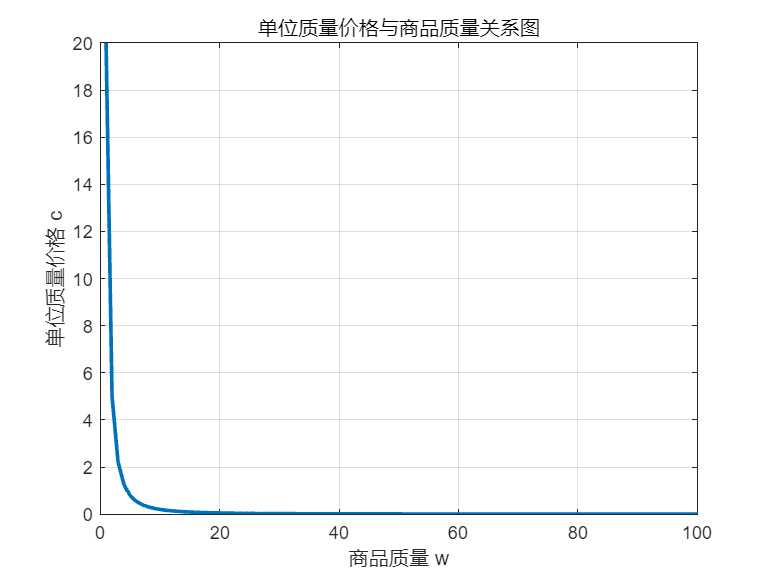

% 定义质量范围和比例系数
w = 1:100; % 商品质量范围
k = 20; % 比例系数

% 计算单位质量价格
c = k ./ w.^2;

% 绘制图表
plot(w, c, 'LineWidth', 2);
xlabel('商品质量 w');
ylabel('单位质量价格 c');
title('单位质量价格与商品质量关系图');
grid on;

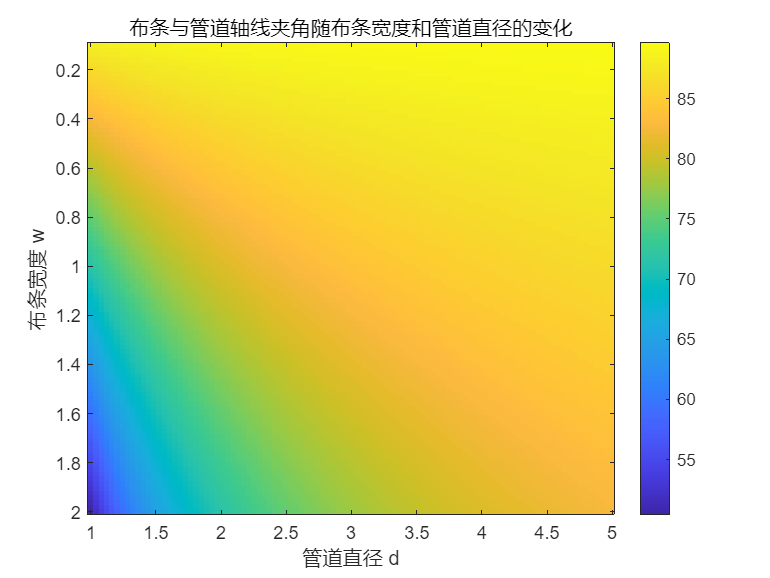

% 定义布条宽度 w 和管道直径 d 的范围
w_range = linspace(0.1, 2, 100); % 布条宽度范围
d_range = linspace(1, 5, 100); % 管道直径范围

% 初始化夹角矩阵
alphas = zeros(length(w_range), length(d_range));

% 计算不同布条宽度和管道直径下的夹角
for i = 1:length(w_range)
    for j = 1:length(d_range)
        w = w_range(i);
        d = d_range(j);
        alpha = acos(w / (pi * d)); % 计算夹角
        alphas(i, j) = rad2deg(alpha); % 转换为角度并存储
    end
end

% 绘制二维热图
figure;
imagesc(d_range, w_range, alphas);
colorbar;
xlabel('管道直径 d');
ylabel('布条宽度 w');
title('布条与管道轴线夹角随布条宽度和管道直径的变化');

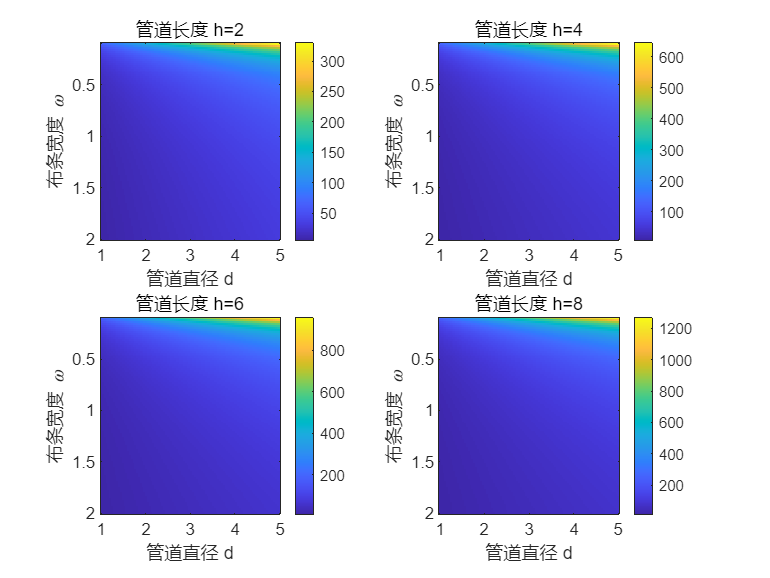

% 定义布条宽度 omega、管道直径 d 和管道长度 h 的范围
omega_range = linspace(0.1, 2, 100); % 布条宽度范围
d_range = linspace(1, 5, 100); % 管道直径范围
h_values = [2, 4, 6, 8]; % 不同的管道长度值

% 初始化长度矩阵
lengths = zeros(length(omega_range), length(d_range), length(h_values));

% 计算不同布条宽度、管道直径和管道长度下的长度
for i = 1:length(omega_range)
    for j = 1:length(d_range)
        for k = 1:length(h_values)
            omega = omega_range(i);
            d = d_range(j);
            h = h_values(k);
            L = (pi * d * h) / omega + sqrt(pi^2 * d^2 - omega^2); % 计算长度
            lengths(i, j, k) = L; % 存储长度
        end
    end
end

% 绘制四张图
figure;
for k = 1:length(h_values)
    subplot(2, 2, k);
    L_plot = lengths(:,:,k); % 获取对应管道长度下的长度矩阵
    imagesc(d_range, omega_range, L_plot);
    colorbar;
    xlabel('管道直径 d');
    ylabel('布条宽度 \omega');
    title(['管道长度 h=', num2str(h_values(k))]);
end

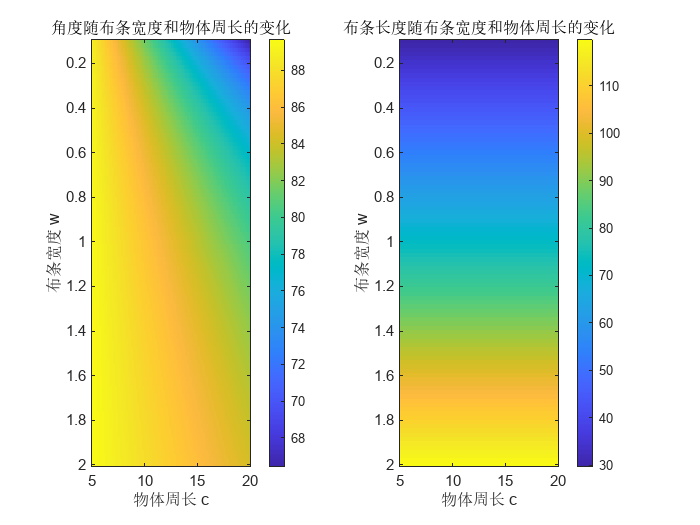

% 定义布条宽度 w、物体周长 c、高度 h 和布条宽度 omega 的范围
w_range = linspace(0.1, 2, 100); % 布条宽度范围
c_range = linspace(5, 20, 100); % 物体周长范围
h = 10; % 高度设定为常数
omega = 2; 

% 初始化角度和长度矩阵
angles = zeros(length(w_range), length(c_range));
lengths = zeros(length(w_range), length(c_range));

% 计算不同布条宽度和物体周长下的角度和长度
for i = 1:length(w_range)
    for j = 1:length(c_range)
        w = w_range(i);
        c = c_range(j);
        alpha = acos(w / c); % 计算角度
        L = (c * h) / omega + sqrt(c^2 - omega^2); % 计算长度
        angles(i, j) = rad2deg(alpha); % 存储角度
        lengths(i, j) = L; % 存储长度
    end
end

% 绘制两张子图
figure;

% 子图1：角度随布条宽度和物体周长的变化
subplot(1, 2, 1);
imagesc(c_range, w_range, angles');
colorbar;
xlabel('物体周长 c');
ylabel('布条宽度 w');
title('角度随布条宽度和物体周长的变化');

% 子图2：长度随布条宽度和物体周长的变化
subplot(1, 2, 2);
imagesc(c_range, w_range, lengths');
colorbar;
xlabel('物体周长 c');
ylabel('布条宽度 w');
title('布条长度随布条宽度和物体周长的变化');

# Second person

clear;clc
South(1,:) = [1,1,1,1];   %南岸
North(1,:) = [0,0,0,0];   %北岸
A = ['人','猫','鸡','米'];
Safe_condition = [1,1,1,1;1,0,1,1;1,1,0,1;1,1,1,0;1,0,1,0;0,0,0,0;0,1,0,0;0,0,1,0;0,0,0,1;0,1,0,1]; %可行的状态
k = 0;                    %记录渡河次数
fprintf('渡河方式: \n');
while (~isequal(North(k+1,:),[1,1,1,1]))&&k<=100
    k = k+1;

渡河方式: 


    for i = 1:4
        flag1 = 0;flag2 = 0;flag3 = 1;  %防止死循环，以及出现不可行的状态
        if South(k,i) ==1
            Cross_river1 = [1,0,0,0];
            Cross_river1(i) = 1;
            South(k+1,:) = xor(South(k,:),Cross_river1);
            North(k+1,:) = [1,1,1,1] - South(k+1,:);
            for j = 1:10
                if isequal(North(k+1,:),Safe_condition(j,:))
                    flag1 = 1;
                end
            end
            for j = 1:10
                if isequal(South(k+1,:),Safe_condition(j,:))
                    flag2 = 1;
                end
            end
            for j = 1:k
                if isequal(South(k+1,:),South(j,:))
                    flag3 = 0;           %防止出现状态死循环
                end
            end
            if (flag1 ==1)&&(flag2 ==1)&&(flag3 ==1)
                if i ==1
                    fprintf('%s 从南岸到北岸\n',A(1));
                    break
                else
                    fprintf('%s 和  %s 从南岸到北岸\n',A(1),A(i));
                    break
                end
            else
                continue
            end
        end
    end
    if isequal(North(k+1,:),[1,1,1,1])
        break
    else
        k = k+1;
        for m = 1:4
            flag1 = 0;flag2 = 0;flag3 = 1;
            if North(k,m) ==1
                Cross_river2 = [1,0,0,0];
                Cross_river2(m) = 1;
                North(k+1,:) = xor(North(k,:),Cross_river2);
                South(k+1,:) = [1,1,1,1] - North(k+1,:);
                for j = 1:10
                    if isequal(North(k+1,:),Safe_condition(j,:))
                        flag1 = 1;
                    end
                end
                for j = 1:10
                    if isequal(South(k+1,:),Safe_condition(j,:))
                        flag2 = 1;
                    end
                end
                for j = 1:k
                    if isequal(South(k+1,:),South(j,:))
                        flag3 = 0;           %防止出现状态死循环
                    end
                end
                if (flag1 ==1)&&(flag2 ==1)&&(flag3 ==1)
                    if m ==1
                        fprintf('%s 从北岸到南岸\n',A(1));
                        break
                    else
                        fprintf('%s 和  %s 从北岸到南岸\n',A(1),A(m));
                        break
                    end
                else
                    continue
                end
            end
        end
    end
end


人 和  鸡 从南岸到北岸


人 从北岸到南岸


人 和  猫 从南岸到北岸


人 和  鸡 从北岸到南岸


人 和  米 从南岸到北岸


人 从北岸到南岸


人 和  鸡 从南岸到北岸


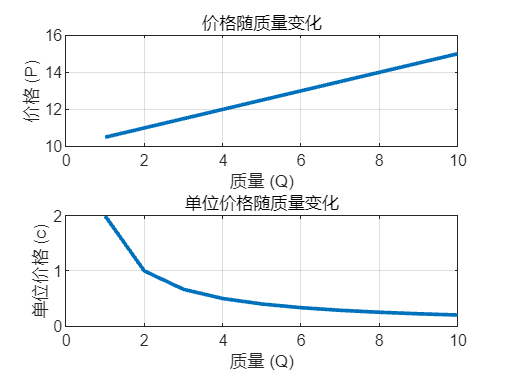

% 定义常数
k1 = 0.5; % 与质量成正比的系数
k2 = 10;  % 与质量无关的成本
k = 2;    % 比例系数

% 定义质量范围
Q_min = 1;
Q_max = 10;

% 初始化存储价格和单位价格的数组
prices = zeros(1, Q_max);
unit_prices = zeros(1, Q_max);

% 计算价格和单位价格
for Q = Q_min:Q_max
    P = k1 * Q + k2;  % 计算价格
    prices(Q) = P;    % 存储价格
    
    c = k * (1 / Q);  % 计算单位价格
    unit_prices(Q) = c;  % 存储单位价格
end

% 绘制价格和单位价格随质量变化的图像
figure;
subplot(2, 1, 1);
plot(Q_min:Q_max, prices,LineWidth=2);
xlabel('质量 (Q)');
ylabel('价格 (P)');
title('价格随质量变化');
grid on

subplot(2, 1, 2);
plot(Q_min:Q_max, unit_prices,LineWidth=2);
xlabel('质量 (Q)');
ylabel('单位价格 (c)');
title('单位价格随质量变化');
grid on

# Third person

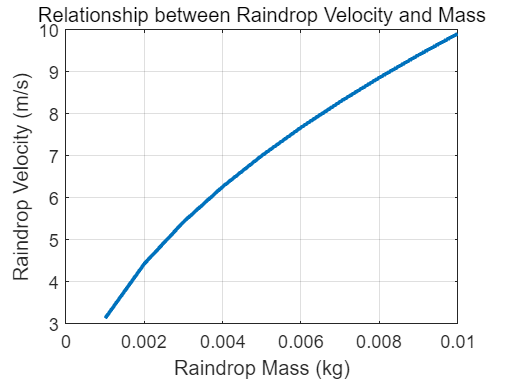

% 定义参数
g = 9.81; % 重力加速度
k = 0.1; % 比例常数
A = 0.01; % 雨滴表面积（假设为常数）
m_range = 0.001:0.001:0.01; % 雨滴质量范围

% 计算雨速
v = sqrt((m_range * g) / (k * A));

% 绘制图表
figure;
plot(m_range, v, 'LineWidth', 2);
xlabel('Raindrop Mass (kg)');
ylabel('Raindrop Velocity (m/s)');
title('Relationship between Raindrop Velocity and Mass');
grid on;

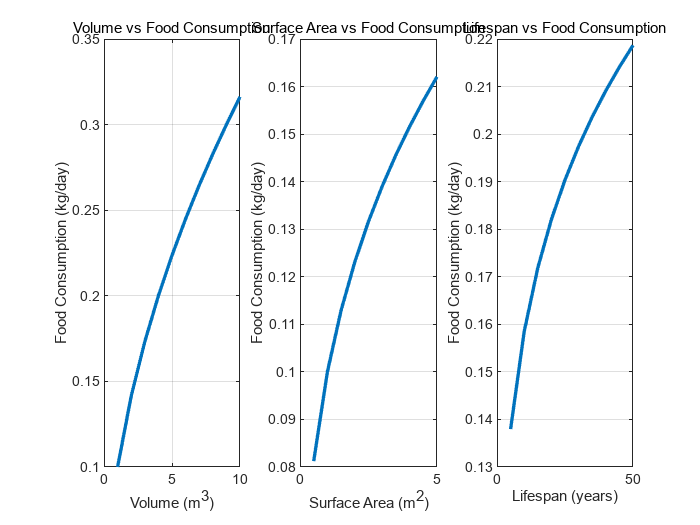

% 定义模型参数
k1 = 0.1; % 系数1
k2 = 0.5; % 系数2
k3 = 0.3; % 系数3
k4 = 0.2; % 系数4

% 定义动物的尺寸范围
V_range = 1:10; % 体积范围
A_range = 0.5:0.5:5; % 表面积范围
L_range = 5:5:50; % 寿命范围

% 计算食物量
F_V = k1 * V_range.^k2;
F_A = k1 * A_range.^k3;
F_L = k1 * L_range.^k4;

% 绘制子图
figure;

subplot(1,3,1);
plot(V_range, F_V, 'LineWidth', 2);
xlabel('Volume (m^3)');
ylabel('Food Consumption (kg/day)');
title('Volume vs Food Consumption');
grid on;

subplot(1,3,2);
plot(A_range, F_A, 'LineWidth', 2);
xlabel('Surface Area (m^2)');
ylabel('Food Consumption (kg/day)');
title('Surface Area vs Food Consumption');
grid on;

subplot(1,3,3);
plot(L_range, F_L, 'LineWidth', 2);
xlabel('Lifespan (years)');
ylabel('Food Consumption (kg/day)');
title('Lifespan vs Food Consumption');
grid on;

# Fourth person

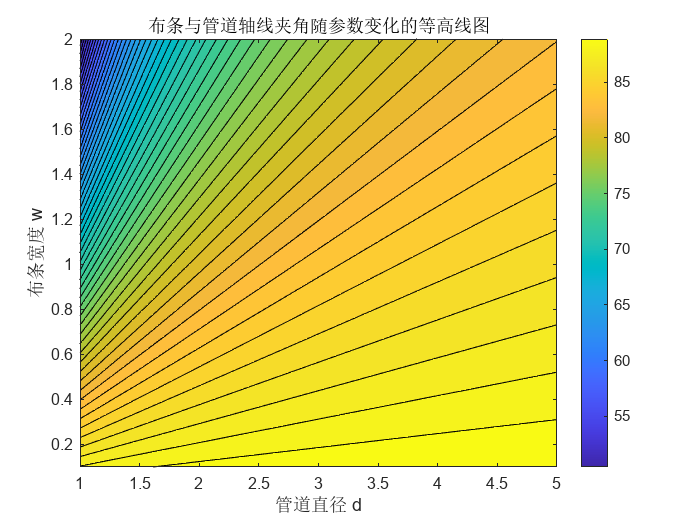

% 定义布条宽度 w 和管道直径 d 的范围
w_range = linspace(0.1, 2, 100); % 布条宽度范围
d_range = linspace(1, 5, 100); % 管道直径范围

% 初始化夹角矩阵
angles = zeros(length(w_range), length(d_range));

% 计算不同布条宽度和管道直径下的夹角
for i = 1:length(w_range)
    for j = 1:length(d_range)
        w = w_range(i);
        d = d_range(j);
        alpha = acos(w / (pi * d)); % 计算夹角
        angles(i, j) = rad2deg(alpha); % 转换为角度并存储
    end
end

% 绘制等高线图
figure;
contourf(d_range, w_range, angles, 50); % 50表示等高线数量，可以根据需要调整
colorbar;
xlabel('管道直径 d');
ylabel('布条宽度 w');
title('布条与管道轴线夹角随参数变化的等高线图');

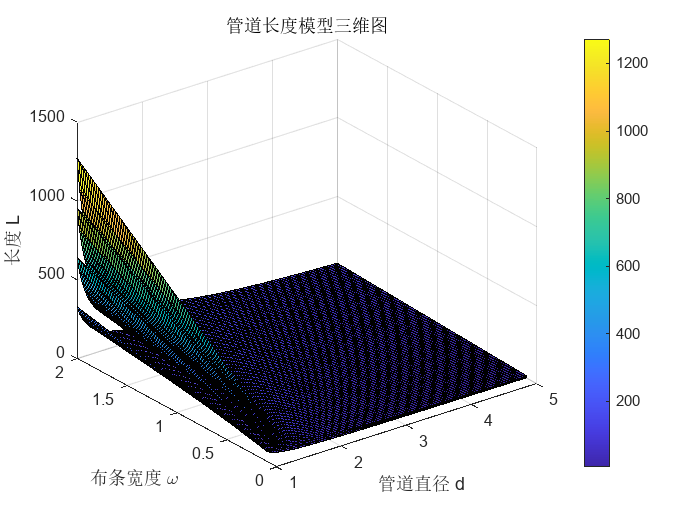

% 定义管道直径 d、布条宽度 omega 和管道长度 h 的范围
d_range = linspace(1, 5, 100); % 管道直径范围
omega_range = linspace(0.1, 2, 100); % 布条宽度范围
h_values = [2, 4, 6, 8]; % 不同的管道长度值

% 初始化长度矩阵
lengths = zeros(length(d_range), length(omega_range), length(h_values));

% 计算不同参数下的长度
for i = 1:length(d_range)
    for j = 1:length(omega_range)
        for k = 1:length(h_values)
            d = d_range(i);
            omega = omega_range(j);
            h = h_values(k);
            L = (pi * d * h) / omega + sqrt(pi^2 * d^2 - omega^2); % 计算长度
            lengths(i, j, k) = L; % 存储长度
        end
    end
end

% 绘制三维图
figure;
for k = 1:length(h_values)
    h = surf(d_range, omega_range, lengths(:, :, k));
    h.FaceAlpha = 0.9; % 设置透明度
    hold on;
end
colorbar;
xlabel('管道直径 d');
ylabel('布条宽度 \omega');
zlabel('长度 L');
title('管道长度模型三维图');

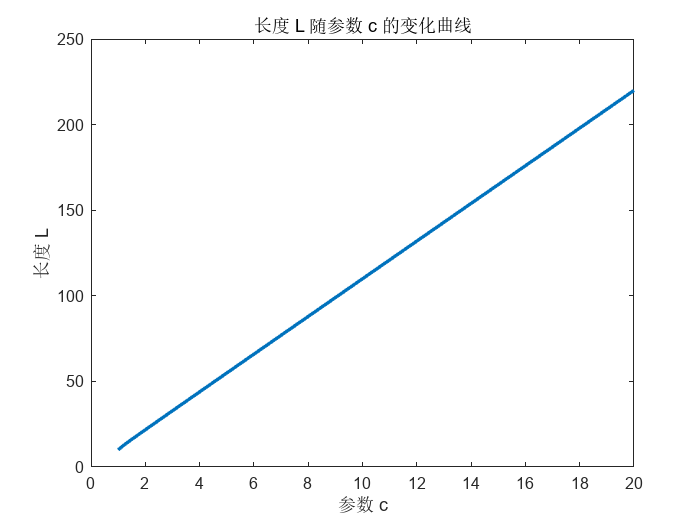

% 定义参数范围和布条宽度 omega
c_range = linspace(1, 20, 100); % 参数 c 的范围
omega = 1; % 布条宽度为固定值
h = 10; % 管道高度为固定值

% 计算长度 L
L = (c_range .* h) / omega + sqrt(c_range.^2 - omega^2); % 模型计算公式

% 绘制曲线图
figure;
plot(c_range, L, 'LineWidth', 2);
xlabel('参数 c');
ylabel('长度 L');
title('长度 L 随参数 c 的变化曲线');

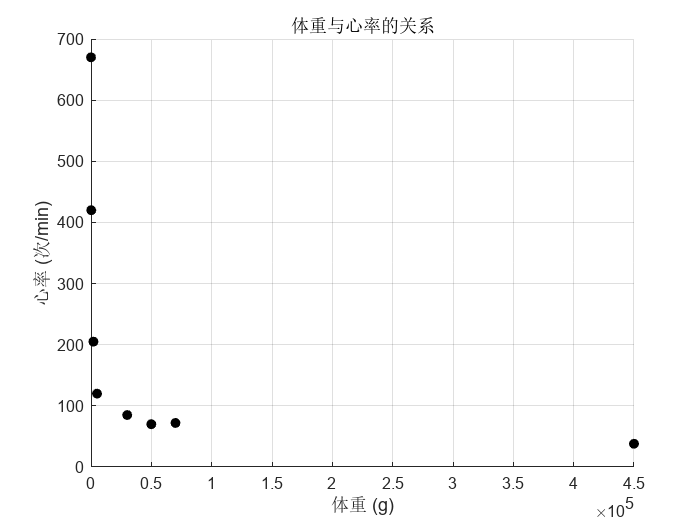

% 所有数据点
weights = [25, 200, 2000, 5000, 30000, 50000, 70000, 450000]; % 体重（g）
heart_rates = [670, 420, 205, 120, 85, 70, 72, 38]; % 心率（次/min）

% 绘制散点图
scatter(weights, heart_rates, 'filled', 'MarkerFaceColor', 'k');
xlabel('体重 (g)');
ylabel('心率 (次/min)');
title('体重与心率的关系');
grid on

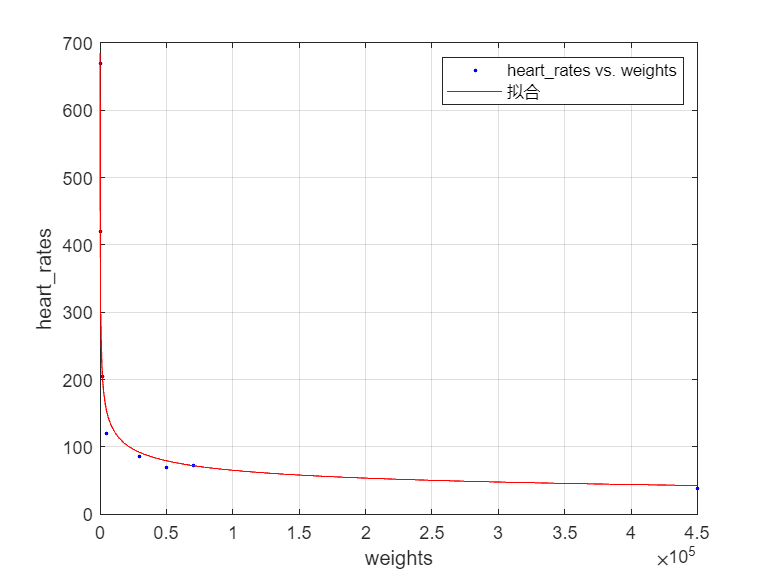


[xData, yData] = prepareCurveData( weights, heart_rates );

% 设置 fittype 和选项。
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1616.19628046008 -0.283102523462745];

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
figure( 'Name', '拟合' );
h = plot( fitresult, xData, yData);
legend( h, 'heart_rates vs. weights', '拟合', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( 'weights', 'Interpreter', 'none' );
ylabel( 'heart_rates', 'Interpreter', 'none' );
grid on

# Fifth person

% 定义目标函数系数向量
f = [-20; -30; -50];

% 定义不等式约束矩阵和右侧向量
A = [1, 1, 1];
b = 12;

% 设置变量下界为0
lb = [0; 0; 0];

% 使用linprog函数求解线性规划问题
[x, maxScore] = linprog(f, [], [], A, b, lb);

找到最优解。




% 输出结果
disp('最优复习时间分配：');

最优复习时间分配：


disp(['数学：', num2str(x(1)), ' 周']);

数学：0 周


disp(['外语：', num2str(x(2)), ' 周']);

外语：0 周


disp(['专业课：', num2str(x(3)), ' 周']);

专业课：12 周


disp(['预计最高得分：', num2str(-maxScore)]);

预计最高得分：600


% 定义目标函数系数向量
f = [-20; -30; -50];

% 定义不等式约束矩阵和右侧向量
A = [1, 0, 0; 0, 1, 0; 0, 0, 1];
b = [60;60;60];  % M、F、P 分别为数学、外语、专业课的及格线分数

% 定义等式约束矩阵和右侧向量
Aeq = [1, 1, 1];
beq = 12;

% 设置变量下界为0
lb = [0; 0; 0];

% 使用linprog函数求解线性规划问题
[x, maxScore] = linprog(f, A, b, Aeq, beq, lb);

找到最优解。




% 输出结果
disp('最优复习时间分配：');

最优复习时间分配：


disp(['数学：', num2str(x(1)), ' 周']);

数学：0 周


disp(['外语：', num2str(x(2)), ' 周']);

外语：0 周


disp(['专业课：', num2str(x(3)), ' 周']);

专业课：12 周


disp(['预计最高得分：', num2str(-maxScore)]);

预计最高得分：600


	% 目标函数系数  
f = [-4.3; -0.5*5.4; -0.5*5.0; -0.5*4.4; -4.5];  
  
% 线性不等式约束条件  
A = [0 1 1 0 0; % x2 + x3 >= 400  
     2 2 0 1 5; % 平均信用等级约束  
     9 15 4 3 2]; % 平均到期年限约束  
b = [400; 1.4*sum((sum(A,2))); 5*sum(sum(A,2))];  
  
% 等式约束条件  
Aeq = [1 1 1 1 1];  
beq = 1000;  
  
% 变量下界  
lb = zeros(5,1);  
  
% 调用linprog求解  
[x, fval] = linprog(f, A, b, Aeq, beq, lb);  

找不到可行解。

Linprog 已停止，因为没有满足约束的点。



  
% 显示结果  
disp('最优投资策略：');  

最优投资策略：


disp(x);  
disp(['最大税后总收益：' num2str(-fval)]);

最大税后总收益：


# Sixth person

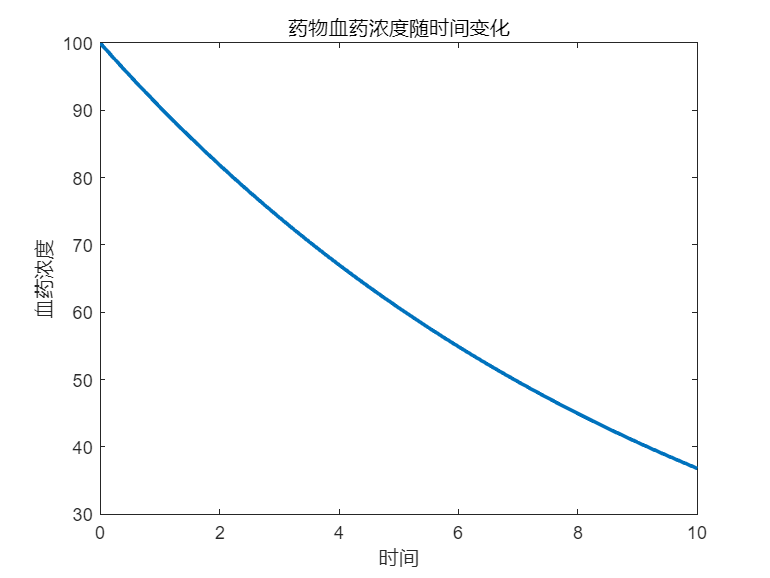

% 参数设置
k = 0.1; % k > 0
x0 = 100; % 初始血药浓度

% 定义微分方程
ode = @(t,x) -k*x;

% 求解微分方程
[t, x] = ode45(ode, [0 10], x0);

% 绘制图像
plot(t, x,LineWidth=2);
xlabel('时间');
ylabel('血药浓度');
title('药物血药浓度随时间变化');

% 参数设置
k = 0.1; % k > 0
x0 = 1000; % 初始血药浓度

% 定义微分方程
ode = @(t,x) -k*x;

% 求解微分方程
[t, x] = ode45(ode, [0 10], x0);

% 绘制图像
plot(t, x,LineWidth=2);
xlabel('时间');
ylabel('血药浓度');
title('药物血药浓度随时间变化');

% 初始条件
S_0 = 100000; % 初始存入金额（元）
monthly_expense = 1000; % 每月生活费（元）
annual_expense = monthly_expense * 12; % 每年生活费总额（元）
annual_interest_rate = 0.004; % 年利率

% 计算老人每年末剩余的钱
years = 0; % 年数
remaining_money = S_0; % 初始剩余金额

fprintf('年份\t\t剩余金额\n');

年份		剩余金额


fprintf('---------------------\n');

---------------------



while remaining_money > annual_expense
    years = years + 1;
    remaining_money = remaining_money * (1 + annual_interest_rate) - annual_expense;
    fprintf('%d\t\t%.2f\n', years, remaining_money);
end

1		88400.00
2		76753.60
3		65060.61
4		53320.86
5		41534.14
6		29700.28
7		17819.08
8		5890.35



fprintf('---------------------\n');

---------------------


fprintf('基金用完的年份：%d\n', years);

基金用完的年份：8



% 计算需要存入的金额以确保基金用到80岁
target_age = 80; % 目标年龄
years_to_target_age = target_age - 60; % 目标年龄与当前年龄的差值
required_amount = annual_expense * (1 + annual_interest_rate)^years_to_target_age; % 所需存入金额
fprintf('存入 %.2f 元以确保基金用到 %d 岁\n', required_amount, target_age);

存入 12997.37 元以确保基金用到 80 岁


# Seventh Person

% 输入数据
temperature = [27.2; 27.2; 27.2; 27.7; 27.7; 27.7; 28.3; 28.3; 28.3; 28.4; 28.4; 28.4; 29.9; 29.9; 29.9];
male_ratio = [0.10; 0.00; 0.111; 0.70; 0.667; 0.75; 1.00; 0.667; 0.875; 0.70; 0.625; 0.778; 0.909; 1.00; 1.00];

% 拟合 logistic 回归模型
mdl = fitglm(temperature, male_ratio, 'linear', 'Distribution', 'binomial');

% 输出模型参数
beta0 = mdl.Coefficients.Estimate(1);
beta1 = mdl.Coefficients.Estimate(2);

% 求解方程
target_ratio = 0; % 目标性别比例为1:1
target_temperature = -beta0 / beta1;

disp(['在孵化温度为 ', num2str(target_temperature), ' 时，幼龟性别比例为 1:1。']);

在孵化温度为 27.7361 时，幼龟性别比例为 1:1。


% 血样为阳性的先验概率
p = 0.01;

% 每组的人数范围
n_min = 1;
n_max = 100; % 假设最大值为 100，可以根据实际情况调整

% 初始化最小平均总检验次数和对应的最优组合
min_total_tests = Inf;
best_combination = [];

% 遍历每组的人数
for n = n_min:n_max
    % 计算一次分组后的平均总检验次数
    T1 = @(k, m) k/2 + m/2;
    
    % 计算二次分组后的平均总检验次数
    T2 = @(k, k_prime, m) k/2 + k_prime/2 + (m - k_prime)/2;
    
    % 遍历混合血样为阳性的组数 k
    for k = 1:n
        % 计算混合血样为阳性的小组数 k_prime
        for k_prime = 1:k
            % 计算二次分组后每小组的人数 m
            for m = 1:n
                % 计算平均总检验次数
                total_tests = T1(k, m) + T2(k, k_prime, m);
                
                % 更新最小平均总检验次数和对应的最优组合
                if total_tests < min_total_tests
                    min_total_tests = total_tests;
                    best_combination = [n, k, k_prime, m];
                end
            end
        end
    end
end

% 输出最小化平均总检验次数和对应的最优组合
disp(['最小化平均总检验次数为：', num2str(min_total_tests)]);

最小化平均总检验次数为：2


disp(['最优组合为：', num2str(best_combination)]);

最优组合为：1  1  1  1


# Eighth Person

% 定义供过于求情况下的收入函数
revenue_surplus = @(x) min(x, 8000).* 0.2.* 50 + max(0, x - 8000) .* 50;

% 定义供不应求情况下的收入函数
revenue_shortage = @(x) min(x, 8000) .* 0.2 .* 50 + max(0, x - 8000) .* 50 - max(0, 8000 - x) .* (15 .* 2);

% 定义期望收入函数
expected_revenue = @(x) integral(@(demand) revenue_surplus(demand) * normpdf(demand, 8000, sqrt(1000)), 0, inf) ...
                      + integral(@(demand) revenue_shortage(demand) * normpdf(demand, 8000, sqrt(1000)), 0, inf);
% 初始猜测的重印量
x0 = 8000;

% 定义约束条件，重印量必须为正数
lb = 0;

% 使用 fmincon 函数进行优化
options = optimoptions(@fmincon,'Display','iter');
[x_optimal, fval] = fmincon(expected_revenue, x0, [], [], [], [], lb, [], [], options);

错误使用  * 
用于矩阵乘法的维度不正确。请检查并确保第一个矩阵中的列数与第二个矩阵中的行数匹配。要单
独对矩阵的每个元素进行运算，请使用 TIMES (.*)执行按元素相乘。

出错 homework (第 575 行)
expected_revenue = @(x) integral(@(demand) revenue_surplus(demand) * normpdf(demand, 8000, sqrt(1000)), 0, inf) ...

出错 integralCalc/iterateScalarValued (第 314 行)
                fx = FUN(t);


% 输出最优解和最大收入
fprintf('最优的重印量为：%d 本\n', x_optimal);
fprintf('最大收入为：%.2f 元\n', -fval);

% 数据输入
X = [
    690 3.1 9 7 4;
    590 3.9 7 6 10;
    600 3.6 8 8 7;
    620 3.8 7 10 6;
    700 2.8 10 4 6;
    650 4.0 6 9 8
];
W = [0.3 0.2 0.2 0.15 0.15];
k = 3; % 奖学金名额

% 加权和法
S = X * W';
[~, idx_sum] = sort(S, 'descend');
selected_sum = idx_sum(1:k);

fprintf('加权和法选中的申请者编号：%d %d %d\n', selected_sum);

加权和法选中的申请者编号：5 1 6



% 加权积法
P = prod(X .^ W, 2);
[~, idx_product] = sort(P, 'descend');
selected_product = idx_product(1:k);

fprintf('加权积法选中的申请者编号：%d %d %d\n', selected_product);

加权积法选中的申请者编号：6 4 3



% TOPSIS 方法
[m, n] = size(X);
% 归一化决策矩阵
X_norm = X ./ sqrt(sum(X.^2, 1));
% 理想解和反理想解
ideal_best = max(X_norm, [], 1);
ideal_worst = min(X_norm, [], 1);
% 计算到理想解和反理想解的距离
distance_best = sqrt(sum((X_norm - ideal_best).^2, 2));
distance_worst = sqrt(sum((X_norm - ideal_worst).^2, 2));
% 计算综合评价指数
C = distance_worst ./ (distance_best + distance_worst);
[~, idx_topsis] = sort(C, 'descend');
selected_topsis = idx_topsis(1:k);

fprintf('TOPSIS 方法选中的申请者编号：%d %d %d\n', selected_topsis);

TOPSIS 方法选中的申请者编号：6 2 4


% 数据输入
t = 0:12;
y = [43.65, 109.86, 187.21, 312.67, 496.58, 707.65, 960.25, 1238.75, 1560.00, 1824.29, 2199.00, 2438.89, 2737.71];
L = 3000;

% 线性化 logistic 增长曲线模型
z = log(L ./ y - 1);

% 线性回归求解参数
p = polyfit(t, z, 1);
alpha = exp(p(2));
omega = -p(1);

fprintf('线性回归估计参数 alpha = %.4f, omega = %.4f\n', alpha, omega);

线性回归估计参数 alpha = 44.8463, omega = 0.4941



% 初始参数
initial_params_logistic = [L, alpha, omega];

% 定义 logistic 函数
logistic = @(params, t) params(1) ./ (1 + params(2) * exp(-params(3) * t));

% Logistic 模型的非线性回归
logistic_params = nlinfit(t, y, logistic, initial_params_logistic);

fprintf('Logistic 非线性回归参数 L = %.4f, alpha = %.4f, omega = %.4f\n', logistic_params);

Logistic 非线性回归参数 L = 3260.4185, alpha = 30.5351, omega = 0.4148



% 初始参数
initial_params_gompertz = [3000, 30, 0.4];

% 定义 gompertz 函数
gompertz = @(params, t) params(1) * exp(-params(2) * exp(-params(3) * t));

% Gompertz 模型的非线性回归
gompertz_params = nlinfit(t, y, gompertz, initial_params_gompertz);

fprintf('Gompertz 非线性回归参数 L = %.4f, b = %.4f, k = %.4f\n', gompertz_params);

Gompertz 非线性回归参数 L = 4810.1269, b = 4.5920, k = 0.1747


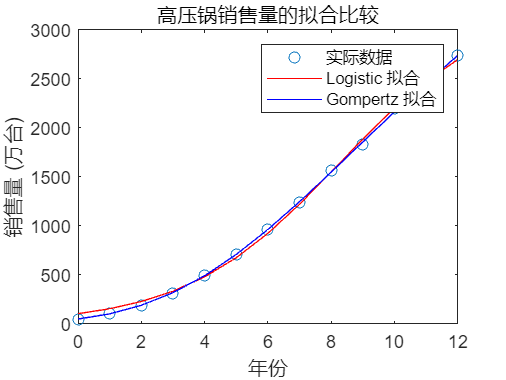


% 拟合结果
y_logistic_fit = logistic(logistic_params, t);
y_gompertz_fit = gompertz(gompertz_params, t);

% 绘图
figure;
plot(t, y, 'o', 'DisplayName', '实际数据');
hold on;
plot(t, y_logistic_fit, '-r', 'DisplayName', 'Logistic 拟合');
plot(t, y_gompertz_fit, '-b', 'DisplayName', 'Gompertz 拟合');
xlabel('年份');
ylabel('销售量 (万台)');
legend;
title('高压锅销售量的拟合比较');
hold off;

# Ninth Person

% 基期价格和数量
p0 = [2, 3, 5];
q0 = [100, 150, 200];

% 现期价格和数量
p = [2.5, 3.5, 6];
q = [110, 140, 210];

% 计算拉氏价格指数
I_L = sum(p .* q0) / sum(p0 .* q0);

% 计算帕氏价格指数
I_P = sum(p .* q) / sum(p0 .* q);

% 输出结果
fprintf('拉氏价格指数: %.4f\n', I_L);

拉氏价格指数: 1.1970


fprintf('帕氏价格指数: %.4f\n', I_P);

帕氏价格指数: 1.1982


mu = 8000;
sigma = 1000;
cost = 15;
price = 50;
discount_price = 10;
extra_cost = 30;

% 正态分布的概率密度函数和累积分布函数
pdf_normal = @(x) normpdf(x, mu, sigma);
cdf_normal = @(x) normcdf(x, mu, sigma);

% 供过于求的期望收入
E_R1 = @(x) 10 * x + 40 * integral(@(D) D .* pdf_normal(D), -Inf, x) / cdf_normal(x);

% 供不应求的期望收入
E_R2 = @(x) 50 * x;

% 总期望收入
E_R = @(x) cdf_normal(x) * E_R1(x) + (1 - cdf_normal(x)) * E_R2(x);

% 使用fminsearch找到使得期望收入最大的 x
options = optimset('Display', 'iter');
[x_opt, max_revenue] = fminsearch(@(x) -E_R(x), mu, options);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -384042         
     1            2          -394782         initial simplex
     2            4          -409756         expand
     3            6          -427970         expand
     4            8          -460000         expand
     5           10          -524000         expand
     6           12          -652000         expand
     7           14          -652000         contract inside
     8           16          -652000         contract inside
     9           18          -652000         contract inside
    10           20          -652000         contract inside
    11           22          -660000         reflect
    12           24          -660000         contract inside
    13           26          -660000         contract inside
    14           28          -660000         contract inside
    15           30          -661000         reflect
    16           32          -661000       

max_revenue = -max_revenue;

% 供不应求且需要加印的情况
% 供过于求的期望收入不变
E_R1_add = @(x) 10 * x + 40 * integral(@(D) D .* pdf_normal(D), -Inf, x) / cdf_normal(x);

% 供不应求的期望收入
E_R2_add = @(x) 20 * integral(@(D) D .* pdf_normal(D), x, Inf) / (1 - cdf_normal(x)) + 30 * x;

% 总期望收入
E_R_add = @(x) cdf_normal(x) * E_R1_add(x) + (1 - cdf_normal(x)) * E_R2_add(x);

[x_opt_add, max_revenue_add] = fminsearch(@(x) -E_R_add(x), mu, options);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -392021         
     1            2          -399391         initial simplex
     2            4          -410878         expand
     3            6          -427985         expand
     4            8          -460000         expand
     5           10          -460000         contract inside
     6           12          -476000         reflect
     7           14          -476000         contract inside
     8           16          -476000         contract inside
     9           18          -480000         reflect
    10           20          -480000         contract inside
    11           22          -482000         reflect
    12           24          -482000         contract inside
    13           26          -482000         contract inside
    14           28          -482500         reflect
    15           30          -482500         contract inside
    16           32          -482750     

max_revenue_add = -max_revenue_add;

fprintf('在正常情况下，年初应重印 %.2f 本书，使出版社平均收入最大，该收入为 %.2f 元。\n', x_opt, max_revenue);

在正常情况下，年初应重印 34138.11 本书，使出版社平均收入最大，该收入为 661381.07 元。


fprintf('在需临时加印的情况下，年初应重印 %.2f 本书，使出版社平均收入最大，该收入为 %.2f 元。\n', x_opt_add, max_revenue_add);

在需临时加印的情况下，年初应重印 16292.36 本书，使出版社平均收入最大，该收入为 482923.61 元。
